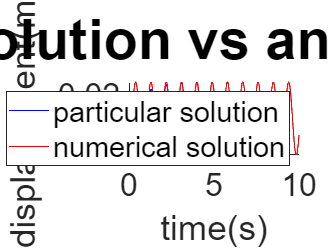

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 2022-1학기 기계진동 term_project
% 해석해로 구한 특수해와 수치해로 구한 전체해의 비교

clear; clc;

% same with problem 1.2 and 1.3
m = 800; k = 4e4; c = 2e3; v = 20;
l = 0.005; hour2sec = 3600;
A = 0.01;

Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
zeta = c/(2*sqrt(k*m));
t1 = 0:0.01:10;

seta1 = atan(2*zeta*Wn*Wb/(Wn^2-Wb^2));
Xp1 = 2*zeta*Wn*Wb*A/sqrt((Wn^2-Wb^2)^2+(2*zeta*Wn*Wb)^2)*cos(Wb*t1-seta1);
Xp2 = Wn^2*A/sqrt((Wn^2-Wb^2)^2+(2*zeta*Wn*Wb)^2)*sin(Wb*t1-seta1);
Xp = Xp1 + Xp2;

x0 = [0; 0];
ts = [0 5];

[t, x] = ode45('project_function_1_3', ts, x0);

% plot
hold on
plot(t, x(:,1), 'b')
plot(t1, Xp, 'r')
hold off
set(gca,'FontSize',24);
title('numerical solution vs analytical solution','FontSize',42,'FontWeight','bold');
xlabel('time(s)');
ylabel('displacement(m)');
legend('particular solution', 'numerical solution');